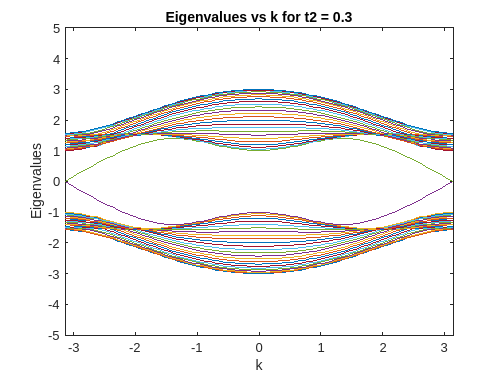

% Define parameters
t1 = 1;
t2 = 0.3;
m = 0;
Ny = 50;
k_values = linspace(-pi, pi, 100);
yvals = 0:Ny-1;
EF0 = 0.0;
EF1 = 1.0;

Eigenvalues = zeros(Ny, numel(k_values));

% Calculate eigenvalues for each k value
for i = 1:numel(k_values)
    Evals_k = eig(H_matrix(t1, t2, k_values(i), m, Ny));
    Eigenvalues(:, i) = Evals_k; 
end

[states,energies] = eig(H_matrix(t1, t2, 3, m, Ny));


%{
density = zeros(1,Ny);
for j = 1:Ny
    density(j) = Spectralfn(EF, yvals(j), states, energies);
end
%}

% Plotting
figure;
plot(k_values, Eigenvalues);
xlabel('k');
ylabel('Eigenvalues');
title(['Eigenvalues vs k for t2 = ' num2str(t2)]);
xlim([-pi, pi]);
ylim([-5, 5]); % Adjust ylim as needed

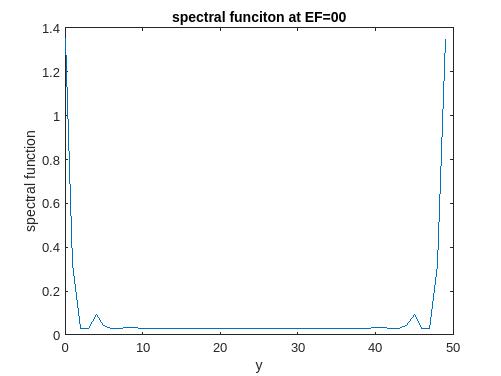

drawnow;

figure;
%plot(yvals, density);
plot(yvals, dens(EF0, yvals, states, energies));
xlabel('y');
ylabel('spectral function');
title(['spectral funciton at EF=0' num2str(EF0)]);

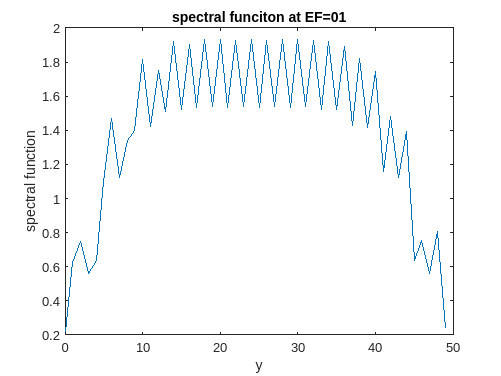

drawnow;

figure;
%plot(yvals, density);
plot(yvals, dens(EF1, yvals, states, energies));
xlabel('y');
ylabel('spectral function');
title(['spectral funciton at EF=0' num2str(EF1)]);

drawnow;

function Mass = Mass(M, N)
    % Initialize the Mass matrix
    Mass = diag(-M .* (-1).^(1:N));
end

function H0 = H0(t1, t2, N)
    % Initialize the H0 matrix
    H0 = -(diag(t1 * ones(1, N-1), 1) + diag(t1 * ones(1, N-1), -1) + ...
        diag(1i * t2 * (-1).^floor((0:N-3)/2), 2) + diag(-1i * t2 * (-1).^floor((0:N-3)/2), -2));
end

function H1 = H1(t1, t2, N)
    % Initialize the H1 matrix
    list1 = repmat([0, 0, t1, 0], 1, ceil(N / 4));
    list2 = repmat([t1, 0, 0, 0], 1, ceil(N / 4));
    list3 = repmat([0, -1i * t2, 1i * t2, 0], 1, ceil(N / 4));
    list4 = repmat([1i * t2, 0, 0, -1i * t2], 1, ceil(N / 4));
    H1 = -(diag(1i * t2 .* (-1).^(1:N)) + diag(list1(1:N-1), 1) + diag(list2(1:N-1), -1) + ...
        diag(list3(1:N-2), 2) + diag(list4(1:N-2), -2));
end

function Evals = Evals(t1, t2, k, M, N)
    % Calculate the matrices H0 and H1
    H0_matrix = H0(t1, t2, N);
    H1_matrix = H1(t1, t2, N);

    % Declare E a variable
    %syms E

    % Calculate the eigenvalues
    Evals = eig(H1_matrix * exp(-1i * k) + H0_matrix + ...
        ctranspose(H1_matrix) * exp(1i * k) + Mass(M, N));
    %determ = det(H1_matrix * exp(-1i * k) + H0_matrix + ... 
    %    ctranspose(H1_matrix) * exp(1i * k) + Mass(M, N) + E * eye(N));
    %Evals = solve(determ,E);
end

function H_matrix = H_matrix(t1, t2, k, M, N)
    % Calculate the matrices H0 and H1
    H0_matrix = H0(t1, t2, N);
    H1_matrix = H1(t1, t2, N);

    % Construct full Hamiltonian
    H_matrix = H1_matrix * exp(-1i * k) + H0_matrix + ...
        ctranspose(H1_matrix) * exp(1i * k) + Mass(M, N);

end

function Spectralfn = Spectralfn(E, y, Psi, Eig)
    element = cell(1,size(Psi,1));
        eta = 0.05;
        for j = 1:size(Psi,1)
            element{j} = (ctranspose(Psi(y+1,j)) * Psi(y+1,j)) / (E - real(Eig(j,j)) + 1i * eta);
        end
        Spectralfn = - imag(sum([element{:}]));
end

function dens = dens(E, yvals, Psi, Eig)
    density = zeros(1,length(yvals));
    for j = 1:length(yvals)
        density(j) = Spectralfn(E, yvals(j), Psi, Eig);
    end
    dens = density;
end